% Process motion probe data to get skull markers coordinates.
% Also, get the tranjectory of mandible during maximum open and close to verify validity.
% Inputs: 
%   - Probe data in Nasion, Subnasale, Left Tragus, Right Tragus
%   - `Probe_Tips_Coordiantes.csv`
% Outputs: `Skull_Markers_Coordinates.csv`

% Add path
addpath(genpath('.\Motion'));
addpath(genpath('.\Registration'));
addpath(genpath('.\SVD'));
addpath(genpath('.\KeyPoints'));
addpath(genpath('.\Probe'));

clear;
clc;

% Preview motion data to manually select indexes
% Probe: nasion
% Probe: subnasale
% Probe: left tragus
% Probe: right tragus

% Params
dataPath = 'C:\Users\Yaolab\Box\6monthVs.12month\Cases\CARSH_00208\02-23-2023\';
motionProbeNasionDataCSVFilePath      = [dataPath, 'Motion_csv\CARSH_00208_02-23-2023_nasion.csv'];      % Motion probe nasion position data
motionProbeSubnasaleDataCSVFilePath   = [dataPath, 'Motion_csv\CARSH_00208_02-23-2023_subnasale.csv'];      % Motion probe subnasale position data
motionProbeLeftTragusDataCSVFilePath  = [dataPath, 'Motion_csv\CARSH_00208_02-23-2023_left tragus.csv'];      % Motion probe left tragus position data
motionProbeRightTragusDataCSVFilePath = [dataPath, 'Motion_csv\CARSH_00208_02-23-2023_right tragus.csv'];      % Motion probe right tragus position data

% Verify trajectory of mandible in maximum open and close oral task
motionDataCSVFilePath = [dataPath, 'Motion_csv\CARSH_00208_02-23-2023_OC.csv'];       % Motion data path

% Read motion probe data from the CSV file
m_motionProbeNasionData      = loadMotionCSVData(motionProbeNasionDataCSVFilePath);

Frame: missing 0 out of 684 data.
TypeNameTimeSeconds: missing 0 out of 684 data.
RigidBodyGlassesRotationX: missing 3 out of 684 data.
RigidBodyGlassesRotationY: missing 3 out of 684 data.
RigidBodyGlassesRotationZ: missing 3 out of 684 data.
RigidBodyGlassesRotationW: missing 3 out of 684 data.
RigidBodyGlassesPositionX: missing 3 out of 684 data.
RigidBodyGlassesPositionY: missing 3 out of 684 data.
RigidBodyGlassesPositionZ: missing 3 out of 684 data.
RigidBodyGlassesMeanMarkerError: missing 3 out of 684 data.
RigidBodyMarkerGlassesMarker1PositionX: missing 3 out of 684 data.
RigidBodyMarkerGlassesMarker1PositionY: missing 3 out of 684 data.
RigidBodyMarkerGlassesMarker1PositionZ: missing 3 out of 684 data.
RigidBodyMarkerGlassesMarker1MarkerQuality: missing 3 out of 684 data.
RigidBodyMarkerGlassesMarker2PositionX: missing 3 out of 684 data.
RigidBodyMarkerGlassesMarker2PositionY: missing 3 out of 684 data.
RigidBodyMarkerGlassesMarker2PositionZ: missing 3 out of 684 data.
RigidBo

m_motionProbeSubnasaleData   = loadMotionCSVData(motionProbeSubnasaleDataCSVFilePath);

Frame: missing 0 out of 708 data.
TypeNameTimeSeconds: missing 0 out of 708 data.
RigidBodyGlassesRotationX: missing 1 out of 708 data.
RigidBodyGlassesRotationY: missing 1 out of 708 data.
RigidBodyGlassesRotationZ: missing 1 out of 708 data.
RigidBodyGlassesRotationW: missing 1 out of 708 data.
RigidBodyGlassesPositionX: missing 1 out of 708 data.
RigidBodyGlassesPositionY: missing 1 out of 708 data.
RigidBodyGlassesPositionZ: missing 1 out of 708 data.
RigidBodyGlassesMeanMarkerError: missing 1 out of 708 data.
RigidBodyMarkerGlassesMarker1PositionX: missing 1 out of 708 data.
RigidBodyMarkerGlassesMarker1PositionY: missing 1 out of 708 data.
RigidBodyMarkerGlassesMarker1PositionZ: missing 1 out of 708 data.
RigidBodyMarkerGlassesMarker1MarkerQuality: missing 1 out of 708 data.
RigidBodyMarkerGlassesMarker2PositionX: missing 1 out of 708 data.
RigidBodyMarkerGlassesMarker2PositionY: missing 1 out of 708 data.
RigidBodyMarkerGlassesMarker2PositionZ: missing 1 out of 708 data.
RigidBo

m_motionProbeLeftTragusData  = loadMotionCSVData(motionProbeLeftTragusDataCSVFilePath);

Frame: missing 0 out of 684 data.
TypeNameTimeSeconds: missing 0 out of 684 data.
RigidBodyGlassesRotationX: missing 4 out of 684 data.
RigidBodyGlassesRotationY: missing 4 out of 684 data.
RigidBodyGlassesRotationZ: missing 4 out of 684 data.
RigidBodyGlassesRotationW: missing 4 out of 684 data.
RigidBodyGlassesPositionX: missing 4 out of 684 data.
RigidBodyGlassesPositionY: missing 4 out of 684 data.
RigidBodyGlassesPositionZ: missing 4 out of 684 data.
RigidBodyGlassesMeanMarkerError: missing 4 out of 684 data.
RigidBodyMarkerGlassesMarker1PositionX: missing 4 out of 684 data.
RigidBodyMarkerGlassesMarker1PositionY: missing 4 out of 684 data.
RigidBodyMarkerGlassesMarker1PositionZ: missing 4 out of 684 data.
RigidBodyMarkerGlassesMarker1MarkerQuality: missing 4 out of 684 data.
RigidBodyMarkerGlassesMarker2PositionX: missing 4 out of 684 data.
RigidBodyMarkerGlassesMarker2PositionY: missing 4 out of 684 data.
RigidBodyMarkerGlassesMarker2PositionZ: missing 4 out of 684 data.
RigidBo

m_motionProbeRightTragusData = loadMotionCSVData(motionProbeRightTragusDataCSVFilePath);

Frame: missing 0 out of 730 data.
TypeNameTimeSeconds: missing 0 out of 730 data.
RigidBodyGlassesRotationX: missing 5 out of 730 data.
RigidBodyGlassesRotationY: missing 5 out of 730 data.
RigidBodyGlassesRotationZ: missing 5 out of 730 data.
RigidBodyGlassesRotationW: missing 5 out of 730 data.
RigidBodyGlassesPositionX: missing 5 out of 730 data.
RigidBodyGlassesPositionY: missing 5 out of 730 data.
RigidBodyGlassesPositionZ: missing 5 out of 730 data.
RigidBodyGlassesMeanMarkerError: missing 5 out of 730 data.
RigidBodyMarkerGlassesMarker1PositionX: missing 5 out of 730 data.
RigidBodyMarkerGlassesMarker1PositionY: missing 5 out of 730 data.
RigidBodyMarkerGlassesMarker1PositionZ: missing 5 out of 730 data.
RigidBodyMarkerGlassesMarker1MarkerQuality: missing 5 out of 730 data.
RigidBodyMarkerGlassesMarker2PositionX: missing 5 out of 730 data.
RigidBodyMarkerGlassesMarker2PositionY: missing 5 out of 730 data.
RigidBodyMarkerGlassesMarker2PositionZ: missing 5 out of 730 data.
RigidBo


% Reorder probe markers
m_motionProbeNasionData      = reorderProbeMarkers(m_motionProbeNasionData);
m_motionProbeSubnasaleData   = reorderProbeMarkers(m_motionProbeSubnasaleData);
m_motionProbeLeftTragusData  = reorderProbeMarkers(m_motionProbeLeftTragusData);
m_motionProbeRightTragusData = reorderProbeMarkers(m_motionProbeRightTragusData);

% Get tips of probe in motive coordinates
m_probeMotiveTips = struct();
m_probeMotiveTips.Nasion      = getTipOfProbe(m_motionProbeNasionData);

Probe alignment accuracy: 0.221572


m_probeMotiveTips.Subnasale   = getTipOfProbe(m_motionProbeSubnasaleData);

Probe alignment accuracy: 0.221576


m_probeMotiveTips.LeftTragus  = getTipOfProbe(m_motionProbeLeftTragusData);

Probe alignment accuracy: 0.221576


m_probeMotiveTips.RightTragus = getTipOfProbe(m_motionProbeRightTragusData);

Probe alignment accuracy: 0.221575



% Read four Probe tips coordinates manually selected
probeGeomagicTipsPath = [dataPath, 'GeomagicFiles\Probe_Tips_Coordinates.csv'];
m_probeGeomagicTips = loadProbeGeomagicTips(probeGeomagicTipsPath);

% Reorder skull markers in probe data
refSkullGeomagicPoints = [
    -68.49, -40.23, -1.30, 35.33, 65.89;
     16.90,   9.44,  8.48, 10.47, 12.16;
     78.06,  45.62, 78.64, 85.29, 75.68;];
m_motionProbeNasionData = reorderSkullMarkers(m_motionProbeNasionData, refSkullGeomagicPoints);

% Get skull markers in motive coordinate system
m_skullMotiveMarkers = [
    m_motionProbeNasionData.RigidBodyMarkerGlassesMarker1PositionX(1), m_motionProbeNasionData.RigidBodyMarkerGlassesMarker2PositionX(1), m_motionProbeNasionData.RigidBodyMarkerGlassesMarker3PositionX(1), m_motionProbeNasionData.RigidBodyMarkerGlassesMarker4PositionX(1), m_motionProbeNasionData.RigidBodyMarkerGlassesMarker5PositionX(1);
    m_motionProbeNasionData.RigidBodyMarkerGlassesMarker1PositionY(1), m_motionProbeNasionData.RigidBodyMarkerGlassesMarker2PositionY(1), m_motionProbeNasionData.RigidBodyMarkerGlassesMarker3PositionY(1), m_motionProbeNasionData.RigidBodyMarkerGlassesMarker4PositionY(1), m_motionProbeNasionData.RigidBodyMarkerGlassesMarker5PositionY(1);
    m_motionProbeNasionData.RigidBodyMarkerGlassesMarker1PositionZ(1), m_motionProbeNasionData.RigidBodyMarkerGlassesMarker2PositionZ(1), m_motionProbeNasionData.RigidBodyMarkerGlassesMarker3PositionZ(1), m_motionProbeNasionData.RigidBodyMarkerGlassesMarker4PositionZ(1), m_motionProbeNasionData.RigidBodyMarkerGlassesMarker5PositionZ(1);];

% Calculate skull markers in geomagic coordinate system
probeSourcePosition = [m_probeMotiveTips.Nasion, m_probeMotiveTips.Subnasale, m_probeMotiveTips.LeftTragus, m_probeMotiveTips.RightTragus];
probeTargetPosition = [m_probeGeomagicTips.Nasion, m_probeGeomagicTips.Subnasale, m_probeGeomagicTips.LeftTragus, m_probeGeomagicTips.RightTragus];

[skullRotationMatrix, skullTranslationVector, accuracy] = svdRigidMotion(probeSourcePosition, probeTargetPosition);

m_skullGeomagicMarkers = skullRotationMatrix * m_skullMotiveMarkers + skullTranslationVector;
fprintf('Probe alignment accuracy: %f\n', accuracy);

Probe alignment accuracy: 5.754981



% Save skull markers coordinates
Names = ["Pt1"; "Pt2"; "Pt3"; "Pt4"; "Pt5"; "Probe alignment accuracy"];
skullMarkersData = [m_skullGeomagicMarkers'; [accuracy, NaN, NaN]];
T = table(Names, skullMarkersData);
writetable(T, [dataPath, 'GeomagicFiles\Skull_Markers_Coordinates.csv'], 'WriteVariableNames', false);

% Verify trajectory of mandible in maximum open and close oral task
% Read motion data from the CSV file
m_motionData = loadMotionCSVData(motionDataCSVFilePath);

Frame: missing 0 out of 2114 data.
TypeNameTimeSeconds: missing 0 out of 2114 data.
RigidBodyGlassesRotationX: missing 2 out of 2114 data.
RigidBodyGlassesRotationY: missing 2 out of 2114 data.
RigidBodyGlassesRotationZ: missing 2 out of 2114 data.
RigidBodyGlassesRotationW: missing 2 out of 2114 data.
RigidBodyGlassesPositionX: missing 2 out of 2114 data.
RigidBodyGlassesPositionY: missing 2 out of 2114 data.
RigidBodyGlassesPositionZ: missing 2 out of 2114 data.
RigidBodyGlassesMeanMarkerError: missing 2 out of 2114 data.
RigidBodyMarkerGlassesMarker1PositionX: missing 2 out of 2114 data.
RigidBodyMarkerGlassesMarker1PositionY: missing 2 out of 2114 data.
RigidBodyMarkerGlassesMarker1PositionZ: missing 2 out of 2114 data.
RigidBodyMarkerGlassesMarker1MarkerQuality: missing 2 out of 2114 data.
RigidBodyMarkerGlassesMarker2PositionX: missing 2 out of 2114 data.
RigidBodyMarkerGlassesMarker2PositionY: missing 2 out of 2114 data.
RigidBodyMarkerGlassesMarker2PositionZ: missing 2 out of 2


% Reorder skull markers order based on relative distance relationship of markers
m_motionData = reorderSkullMarkers(m_motionData, m_skullGeomagicMarkers);

% Get mandible markers position based on skull markers in CBCT, skull
% markers in motion, mandible markers in motion
m_mandibleGeomagicPoints = registerMandibleBySkull(m_motionData, m_skullGeomagicMarkers);

% Fix skull position based on skull markers in CBCT
m_motionData = fixSkullMarkers(m_motionData, m_skullGeomagicMarkers);

Frame 1, Alignment accuracy: 0.000004
Frame 2, Alignment accuracy: 0.000007
Frame 3, Alignment accuracy: 0.000003
Frame 4, Alignment accuracy: 0.000004
Frame 5, Alignment accuracy: 0.000005
Frame 6, Alignment accuracy: 0.000004
Frame 7, Alignment accuracy: 0.000004
Frame 8, Alignment accuracy: 0.000007
Frame 9, Alignment accuracy: 0.000004
Frame 10, Alignment accuracy: 0.000005
Frame 11, Alignment accuracy: 0.000007
Frame 12, Alignment accuracy: 0.000006
Frame 13, Alignment accuracy: 0.000005
Frame 14, Alignment accuracy: 0.000007
Frame 15, Alignment accuracy: 0.000004
Frame 16, Alignment accuracy: 0.000006
Frame 17, Alignment accuracy: 0.000006
Frame 18, Alignment accuracy: 0.000003
Frame 19, Alignment accuracy: 0.000006
Frame 20, Alignment accuracy: 0.000005
Frame 21, Alignment accuracy: 0.000005
Frame 22, Alignment accuracy: 0.000007
Frame 23, Alignment accuracy: 0.000007
Frame 24, Alignment accuracy: 0.000005
Frame 25, Alignment accuracy: 0.000007
Frame 26, Alignment accuracy: 0.00

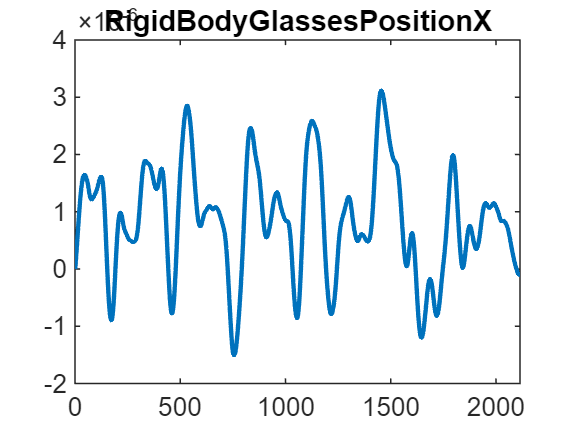

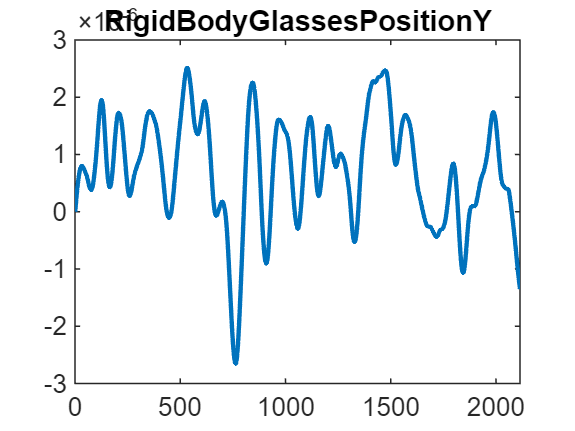

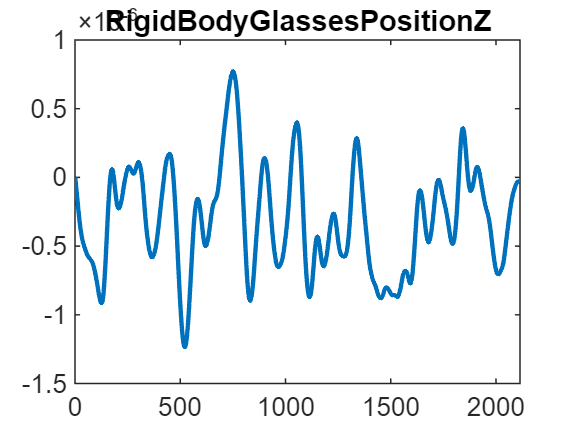

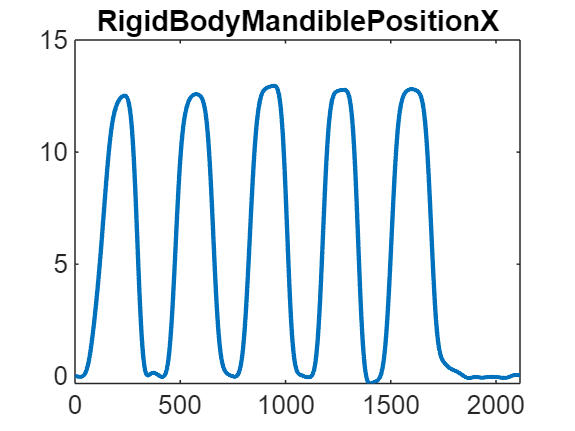

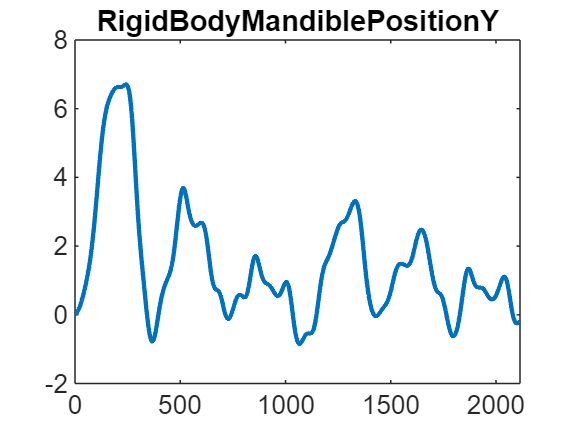

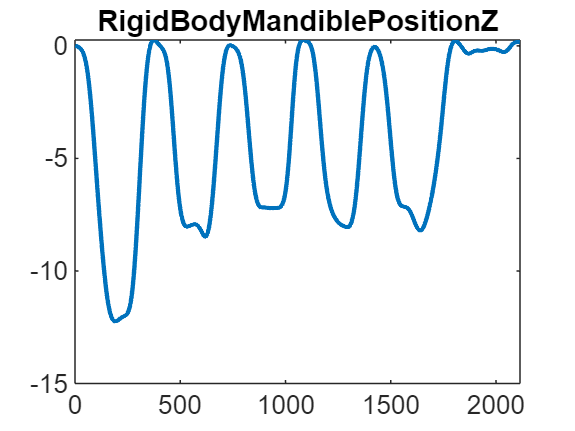


% Filter motion data
m_motionData = filterMotionData(m_motionData);

% Smooth motion data
m_motionData = smoothMotionData(m_motionData);

% View motion data
viewMotionData(m_motionData)

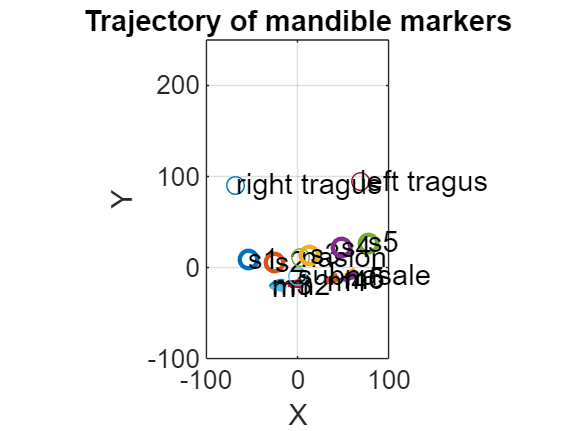

scatter3(m_probeGeomagicTips.Nasion(1), m_probeGeomagicTips.Nasion(2), m_probeGeomagicTips.Nasion(3));
text(m_probeGeomagicTips.Nasion(1), m_probeGeomagicTips.Nasion(2), m_probeGeomagicTips.Nasion(3), 'nasion');
scatter3(m_probeGeomagicTips.Subnasale(1), m_probeGeomagicTips.Subnasale(2), m_probeGeomagicTips.Subnasale(3));
text(m_probeGeomagicTips.Subnasale(1), m_probeGeomagicTips.Subnasale(2), m_probeGeomagicTips.Subnasale(3), 'subnasale');
scatter3(m_probeGeomagicTips.LeftTragus(1), m_probeGeomagicTips.LeftTragus(2), m_probeGeomagicTips.LeftTragus(3));
text(m_probeGeomagicTips.LeftTragus(1), m_probeGeomagicTips.LeftTragus(2), m_probeGeomagicTips.LeftTragus(3), 'left tragus');
scatter3(m_probeGeomagicTips.RightTragus(1), m_probeGeomagicTips.RightTragus(2), m_probeGeomagicTips.RightTragus(3));
text(m_probeGeomagicTips.RightTragus(1), m_probeGeomagicTips.RightTragus(2), m_probeGeomagicTips.RightTragus(3), 'right tragus');
xlim([-100, 100]);
ylim([-100, 250]);
zlim([-250, 150]);

% Remove path
rmpath(genpath('.\Motion'));
rmpath(genpath('.\Registration'));
rmpath(genpath('.\SVD'));
rmpath(genpath('.\KeyPoints'));
rmpath(genpath('.\Probe'));